# Optimisation globale : évaluation 2021

Par, Alan GANY et Jérémy CLAUDE

#### **Partie 1 : optimisation mono-objectif.**

Dans cette partie, on s'interessera au fonctionnement d'une pile en été, La pile à combustible ne fonctionne donc pas. 

**1.1) Import et définition des variablles et bases de données necessaires à la résolution. **

data = load('EteV35Nu10.txt');

D = data(:,2); %Demande en été
Ppv = data(:,4); %Production PV en été 
Peol = data(:,5); %Production éol en été 
Prix = data(:,3); %Prix de la Puissance ext 

N = length(D);
Pelecmin = 5; %Puissance minimale injectée dans la pile en MW par h
Pelecmax = 30; %Puissance maximale injectée dans la pile en MW par h
etha = 0.6; %Rendement de la pile
Qh2min = linspace(100,300,4); %4 demmandes journalières d'energie pour la pile en MWh 

**1.2) Définiton des fonctions objectives. **

Pour pouvoir réaliser cette recherche opérationnelle, nous avons dans un premier temps défini deux fonctions objectives, ayant pour objectif toutes deux, de minimiser l'achat de puissance en provenance du réseau, autrement dit, de minimiser le cout de la puissance ext consomée, tout en rechargeant la pile. 

Si il y a deux fonctions disctinctes, c'est que l'un des algorithme utilisé demandait comme variable de la fonction un vecteur colonne, lorsque l'autre demandait un vecteur ligne. 

%Définition des fonctions objectives 
f = @(P)  (D - Ppv - Peol + P)'*Prix;
f2 = @(P)  (D' - Ppv' - Peol' + P)*Prix;

**1.3) Définitions des contraintes et des bornes**

Nous avons considéré qu'une seule contrainte inégalité, retranscrivant le fait que chaques jours la pile doit recevoir "QH2min" energie. 


%Contraintes égalité 
%Contraintes inégalité
Aineq1 = -ones(1,N)*etha;
bineq1 = -Qh2min(1);


%% Bornes 
lb1 = ones(N,1)*Pelecmin;
ub1 = ones(N,1)*Pelecmax;

%% Initialisation 

x01 = lb1;

**1.4.1) Résolution du problème à l'aide d'un multistart. **

ms = MultiStart;
k = 1000;

probleme = createOptimProblem('fmincon');
probleme.x0 = x01;
probleme.lb = lb1;
probleme.Aineq = Aineq1;
probleme.bineq = bineq1;
probleme.ub=ub1;
probleme.objective = f;

[x,fval,exitflag,output,solutions]=run(ms,probleme,k);

MultiStart completed the runs from all start points.

All 1000 local solver runs converged with a positive local solver exit flag.


**1.4.1) Résolution du problème à l'aide d'un algo génétique. **

[x2,fval2,exitflag2,output2,population,scores] = ga(f2,N,Aineq1,bineq1,[],[],lb1,ub1);

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


**1.5) Comparaison entre les deux algos **

## Comparaison entre algos

fprintf('La puissance emagasinée par la pile est de %d MW pour multistart et de %d MW pour le ga  \n',sum(x),sum(x2)');

La puissance emagasinée par la pile est de 1.666667e+02 MW pour multistart et de 1.666650e+02 MW pour le ga  


fprintf('Le cout est de %d Euros pour multistart et de %d Euros pour le ga  \n',fval,fval2');

Le cout est de 3.332033e+04 Euros pour multistart et de 3.360084e+04 Euros pour le ga  


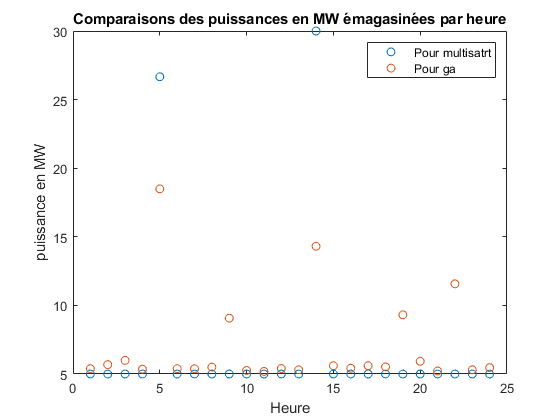

plot([x x2'],'o')
title('Comparaisons des puissances en MW émagasinées par heure')
xlabel('Heure')
ylabel('puissance en MW')
legend('Pour multisatrt','Pour ga')

Remarque : 

On remarque sur ce graphe deux stratégies différentes réalisées par chaque algo. 

La stratégie du multistart est d'acheter beaucoup de puissance au réseau, dès que le coût de cette dernière est moindre et de ce tenir au minimum imposé dans le cas écheant, alors que ga propose d'en acheter de façon plus difuse la puissance au réseau. Pour finalement deux coûts très similaire. 

**1.6) Pour plusieurs demande de Pelec journalière : **

donnees = [];
for i = 1:length(Qh2min)
    bineq1 = -Qh2min(i);
    [x2,fval2,exitflag2,output2,population,scores] = ga(f2,N,Aineq1,bineq1,[],[],lb1,ub1);
    donnees = [donnees x2'];
end

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


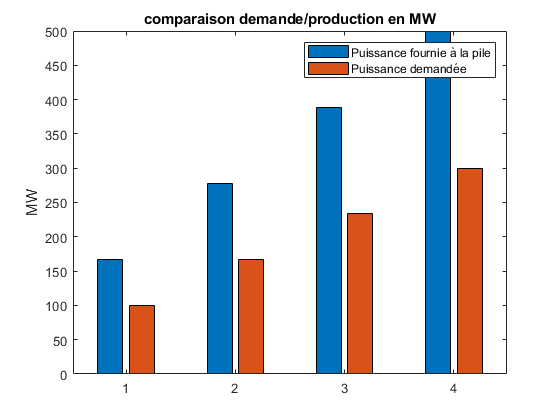


bar([sum(donnees,1)' Qh2min'])
title('comparaison demande/production en MW')
xlabel('')
ylabel('MW')
legend('Puissance fournie à la pile','Puissance demandée')

On remarque que l'on produit relativement plus que demandé à chaque fois. 

**Partie 2 : optimisation multi-objectif.**

**1.2) Import et définition des variables et bases de données necessaires à la résolution. **

clear all
data2 = load('AutonV50Nu40.txt');

D2 = data2(:,2);
Ppv2 = data2(:,4);%Production PV en hiver
Peol2 = data2(:,5);%Production éol en hiver
Prix2 = data2(:,3);%Prix de la Puissance ext 

N2 = length(D2);

%% données
coutpac= 4; %Gain en euro pour 1MW fourni par la PAC
QH2max = 20; %energie max fourni par la PAC en MW par h
ethapac = 0.8; % Rendemant de la PAC
Pelecmin = 5; %Puissance minimale à stocker en MW 
Ppacmax = 15; %Puissance max fourni par la PAC en MW
Pelecmax = 30; %Puissance maximale à stocker en MW 
Pminelec = 5;


**2.2) Définiton de la fonction objective. **

Pour pouvoir réaliser cette recherche opérationnelle, nous avons défini une fonction objective, ayant pour objectif de minimiser l'achat de puissance en provenance du réseau tout en consomant de l'electricité en provenance de la PAC, autrement dit, de minimiser le cout de la puissance ext consomée, tout en rechargeant autant que possible la pile. 

Dans ce code, les N premières composantes de x représentent les puissances utilisées par la PAC toutes les heures, et les N dernières composantes de x représente les 24 Pelec.  (N=24, nb d'heures dans une journée)

f = @(x) [sum(x(1:N2));(D2- Peol2 -Ppv2+x(N2+1:2*N2)')'*Prix2- sum(x(1:N2))*coutpac];

**2.3) Définitions des contraintes et des bornes**

Nous avons considéré deux contraintes inégalités, l'une retranscrivant le fait que chaque jours la pile ne puisse délivrer QH2max energie et l'autre le fait que chaque jour doit au moins être produit Pminelec. 

% contraintes 
Aineq = [ones(1,N2)*ethapac zeros(1,N2);zeros(1,N2) -ones(1,N2)];
bineq = [QH2max -Pminelec];

% bornes 
lb = [zeros(2*N2,1)];
ub = [ones(N2,1)*Ppacmax ones(N2,1)*Pelecmax];

**2.4.1) Résolution pour Paretosearch **

%% calcul du front de pareto 
options=optimoptions("paretosearch");
[xpa1,fval1,exitflag,output,residuals] = paretosearch(f,2*N2,Aineq,bineq,[],[],lb,ub,[],options);


Pareto set found that satisfies the constraints. 

Optimization completed because the relative change in the spread of the Pareto set 
is less than 'options.ParetoSetChangeTolerance' and constraints are satisfied to within 
'options.ConstraintTolerance'.



**2.4.2) Résolution pour gamultiobj**

options=optimoptions("gamultiobj");
[xga1,fval2,exitflag2,output2,residuals2]=gamultiobj(f,2*N2,Aineq,bineq,[],[],lb,ub,[],options);

Optimization terminated: average change in the spread of Pareto solutions less than options.FunctionTolerance.


**2.5.1) Test avec plusieurs valeurs de QH2max et pelec min**

Qh2maxL=[15:5:20]

Qh2maxL =     15    20


pelecminL=[4:1:5]

pelecminL =      4     5


Result_Pareto=[]


Result_Pareto =

     []




for i = 1:length(Qh2maxL)
    for j=1:length(pelecminL)
        bineqt = [Qh2maxL(i), pelecminL(j)]
            [x_p,fval3,exitflag,output,residuals] = paretosearch(f,2*N2,Aineq,bineqt,[],[],lb,ub,[],optimoptions('paretosearch'));
            %[x_ga,fval2,exitflag2,output2,residuals2]=gamultiobj(f,2*N2,Aineq,bineqt,[],[],lb,ub,[],optimoptions('gamultiobj'));
            Result_Pareto = [Result_Pareto fval3];
            %Result_GA=[Result_GA x_ga'];
    end
end

bineqt =     15     4



Pareto set found that satisfies the constraints. 

Optimization completed because the relative change in the volume of the Pareto set 
is less than 'options.ParetoSetChangeTolerance' and constraints are satisfied to within 
'options.ConstraintTolerance'.



bineqt =     15     5



Pareto set found that satisfies the constraints. 

Optimization completed because the relative change in the volume of the Pareto set 
is less than 'options.ParetoSetChangeTolerance' and constraints are satisfied to within 
'options.ConstraintTolerance'.



bineqt =     20     4



Pareto set found that satisfies the constraints. 

Optimization completed because the relative change in the spread of the Pareto set 
is less than 'options.ParetoSetChangeTolerance' and constraints are satisfied to within 
'options.ConstraintTolerance'.



bineqt =     20     5



Pareto set found that satisfies the constraints. 

Optimization completed because the relative change in the spread of the Pareto set 
is less than 'options.ParetoSetChangeTolerance' and constraints are satisfied to within 
'options.ConstraintTolerance'.



%récupération des résultats dans deux vecteurs différent 
Result_Pareto1 = Result_Pareto(:,1:2);
Result_Pareto2 = Result_Pareto(:,3:4);



**Remarque importante : **

On souhaitait faire une optimisation mixte, pour définir des moments ou la pile foncitonnait et donc ne se rechargeait pas et inversement. MAIS, alors que gamultiobj, selon la doc en ligne (que l'on trouve grace à un navigateur), admet des variables entières, ce n'est pas le cas sur notre version de optimization toolbox. 

**2.6) Comparaison des fronts de paretos**

**Pour Paretosearch**

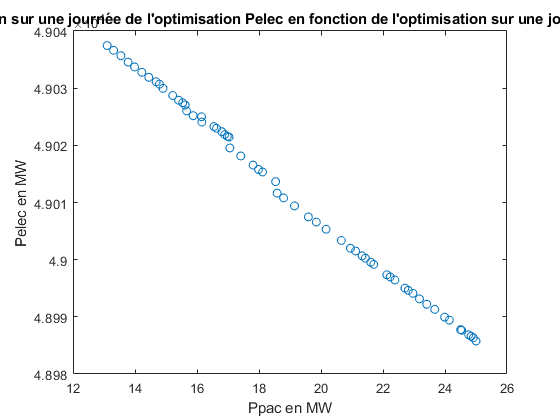

%Pareto1 = [sum(xpa1(:,1:N2),2) sum(xpa1(:,N2+1:2*N2),2)];
plot(fval1(:,1),fval1(:,2),'o')
title("visualisation sur une journée de l'optimisation Pelec en fonction de l'optimisation sur une jounrée de Ppac")
xlabel('Ppac en MW')
ylabel('Pelec en MW')

**Pour gamultiobj**

Même raisonnement. 

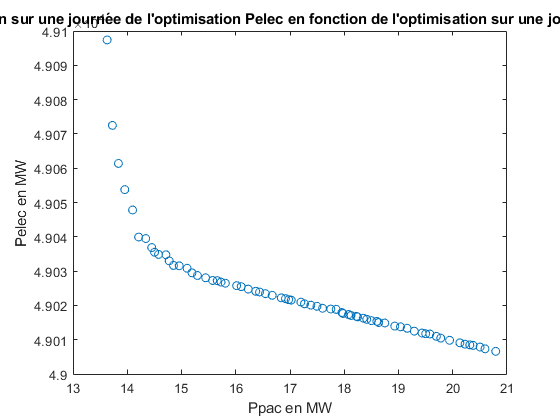

%Pareto2 = [sum(xga1(:,1:N2),2) sum(xga1(:,N2+1:2*N2),2)];
plot(fval2(:,1),fval2(:,2),'o')
title("visualisation sur une journée de l'optimisation Pelec en fonction de l'optimisation sur une jounrée de Ppac")
xlabel('Ppac en MW')
ylabel('Pelec en MW')

**2.7) Comparaison entre deux front de pareto pour deux valeurs de QH2max et Pelemin différentes pour paretosearch**

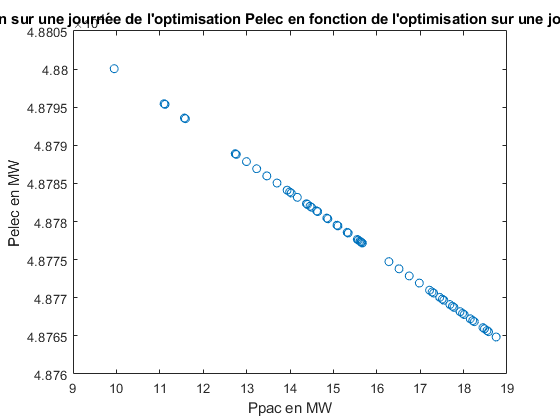


%Pareto3 = [sum(Result_Pareto1(:,1:N2),2) sum(Result_Pareto1(:,N2+1:2*N2),2)];
%Pareto4 = [sum(Result_Pareto2(:,1:N2),2) sum(Result_Pareto2(:,N2+1:2*N2),2)];
plot(Result_Pareto1(:,1),Result_Pareto1(:,2),'o')
title("visualisation sur une journée de l'optimisation Pelec en fonction de l'optimisation sur une jounrée de Ppac")
xlabel('Ppac en MW')
ylabel('Pelec en MW')

plot(Result_Pareto2(:,1),Result_Pareto2(:,2),'o')
title("visualisation sur une journée de l'optimisation Pelec en fonction de l'optimisation sur une jounrée de Ppac")
xlabel('Ppac en MW')
ylabel('Pelec en MW')

**Conclusion : **

  On obserbe que quelque soit QH2, l'allule du front de pareto reste la même. Ce resultat est logique vu que le fait de consomé de l'electricité pour Pelec n'influ pas sur le fait d'utiliser la pile. 

On aurait alors pu, grâce à des variables non mixtes faire en sorte que la pile ne fonctionne pas en même temps que l'éléctrolyseur, ce qui aurait été plus interessant. Malheuresement des contraintes technique nous ont empéché de le faire. 